# 函数与外部数据操作

## 外部数据操作

### 1.1 写入外部文件

x = 0:0.01:20;
y = 0.8*exp(-0.5*x).*sin(10*x);
Fid = fopen('TXT/exp_1.txt','wt');
fprintf(Fid,'%6.2f',y);
fclose(Fid);

### 1.2 读取外部文件数据

Fid = fopen('TXT/exp_1.txt','rt');
r = fscanf(Fid,'%f',inf);
fclose(Fid);
plot(r);

### 2.1 获取用户输入

n_1 = input('Please input an int:')
n_2 = input('请输入运算表达式：')
s_1 = input('请输入一个字符串:','s')
s_2 = input('请输入一个字符串:\n','s') %换行输入

### 3.1 程序的调试和表演

%编写100-200中不能被3和7整除的数

n=100;m=200;
result=[];
echo on
while n <=m
    if(mod(n,3)==0)&&(mod(n,7)==0)
        disp(strcat(num2str(n),'能被3和7整除'));
    else
        result=[result,n];
        disp(strcat(num2str(n),'是程序要找的数值'));
    end
    pause(1)
    n = n+1;
end
result

### 4.1 日期和时间的使用

date函数 按照日期字符串格式返回当前系统日期； now函数 %按照连续日期数值格式返回当前系统时间； clock函数 %按照日期向量格式返回当前系统时间。

D = date
N = now
C = clock
datestr(D,26)
datenum(D)
datevec(D)

# MATLAB的绘图

### 1.1绘图窗口

% 定义x的取值范围和曲线y的表达式
x = 0:0.1:10;
y = sin(x);
plot(y)
% 选中工作区的变量y，点击工具栏上方的绘图，选择需要绘制的图像即可

### 1.2 二维绘图

% 创建指定区域的绘图窗口
figure_exp1 = figure('Name','实例图形窗口','Position',[300 200 600 600]);

### 1.2.1 绘制line线图

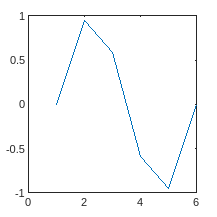

x=0:0.4*pi:2*pi; %定义x轴取值范围
y=sin(x); %定义曲线y
% figure_exp_1 = line(x,y) %使用line函数绘制直线

y1 = sin(x);
y2 = cos(x);
y3 = sin(x-0.1*pi);
y4 = cos(x+0.1*pi);

plot(y1)

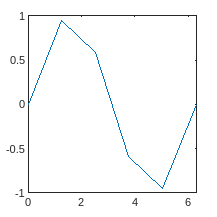

plot(x,y1)

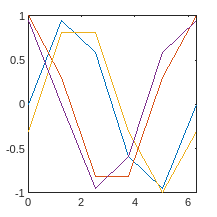

plot(x,[y1;y2;y3;y4])

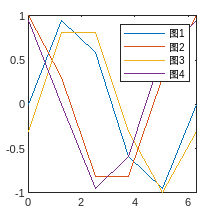

plot(x,y1,x,y2,x,y3,x,y4)
legend('图1', '图2' ,'图3' ,'图4')